# **Deep Learning in Quantitative Finance:** LSTM Networks for Regression

This demo is to show how to use Long Short-Term Memory (LSTM) networks to predict the daily Nominal Broad U.S. Dollar Index ("DTWEXBGS") in MATLAB. We predict the trend of this index. Set an initial value for investment on this index, and use the predict value to trade. 

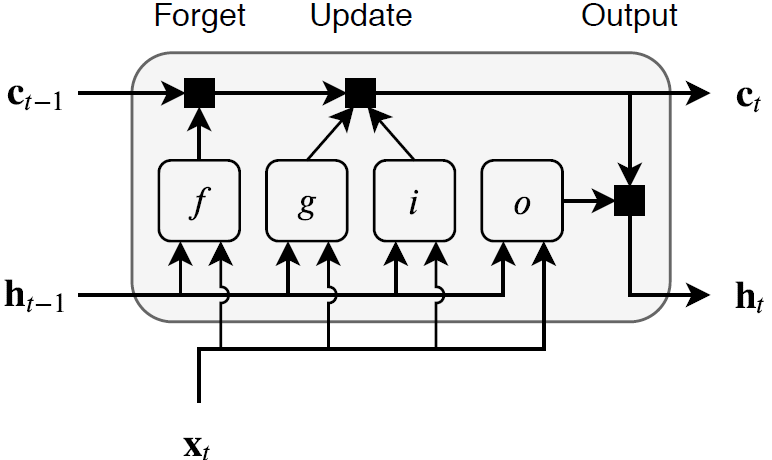

This diagram illustrates the flow of data at time step $t$. This diagram shows how the gates forget, updata, and output the cell and hidden states. More details can be found in documentation [Long Short-Term Memory Neural Networks](https://www.mathworks.com/help/deeplearning/ug/long-short-term-memory-networks.html).

Requires: MATLAB R2023a, Datafeed Toolbox™**, **Statistics and Machine Learning Toolbox™ and Neural Network Toolbox™

% clear
% clc
% warning off


## **Getting data: US_CO2 as data, Years as dates**

- changing datat

% c = fred;
% series = 'DTWEXBGS'; 
% d = fetch(c,series);
% close(c)
% dates = datetime(d.Data(:,1),'ConvertFrom','datenum');
% data = d.Data(:,2);
% DateRange = dates <= datetime(2021,12,31);
% 
% dates = dates(DateRange);
% data = data(DateRange);
dates_year=Years(:,6:end)

dates_year =         1905        1906        1907        1908        1909        1910        1911        1912        1913        1914        1915        1916        1917        1918        1919        1920        1921        1922        1923        1924        1925        1926        1927        1928        1929        1930        1931        1932        1933        1934        1935        1936        1937        1938        1939        1940        1941        1942        1943        1944        1945        1946        1947        1948        1949        1950        1951        1952        1953        1954


data=US_CO2

data = 1.0e+03 *

    0.9865
    1.0355
    1.2039
    1.0528
    1.1657
    1.2716
    1.2587
    1.3436
    1.4425
    1.3180


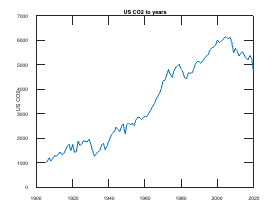


plot(dates_year,data)
hold on
title("US CO2 to years")
ylabel("US CO2")
% annotation('arrow',[0.6044,0.6494],[0.7598,0.6782]);
% annotation('arrow',[0.6528,0.5805],[0.381,0.4262]);
% annotation('arrow',[0.4997,0.4122],[0.1812,0.1581]);
hold off

From the plot, there are several missing values. The arrow points out some missing values. The next step is to clean the data and preprocess the data for training.

## Data Cleaning

Remove the missing values. Adjust data into sequences with lags

if sum(ismissing(data))
    xRaw = rmmissing(data); % remove missing values
else
    xRaw = data;
end

dates_year = dates_year(~ismissing(data));

Create indices for partitioning data into training set and testing set

% nTest = sum(year(dates) == year(dates(end))); % Number of test days: Last year
% nTrain = numel(xRaw) - (nTest+1);

nTest=uint8(numel(dates_year)*0.2); %给更多的训练集：2-8
nTrain=numel(xRaw) - (nTest+1);
idxTrain = (1:nTrain)';
idxTest = (nTrain+1:numel(xRaw))';

datesTrain = dates_year(idxTrain);
datesTest = dates_year(idxTest);

Standardize data for both training and testing

[x1, mu1, sigma1] = standardizeByCol(xRaw(idxTrain));
x2 = (xRaw(idxTest) - repmat(mu1,nTest+1,1)) ./ repmat(sigma1,nTest+1,1); % standardize test data using training data mean and standard deviation
xNorm = [x1; x2];

Create a response variable

- 调整sequence length，不用太小，20/40

sequenceLength = 20;
Y = xNorm(sequenceLength+1:end-1,1);
nFeatures = size(xNorm,2); % num columns in data

Create lags

nrows = size(xNorm,1) + 1 - sequenceLength ;
for row = 1: nrows-1
    X{row} = xNorm(row:sequenceLength+row-1,:)';
end
X = X';
X = X(1:end-1,:);
% clear xRaw yRaw c d series xNorm nrows row

Partion data into training set and testing set

XTrain = X(1:end-nTest,:);
YTrain = Y(1:end-nTest,:);
XTest = X(end-nTest+1:end,:);
YTest = Y(end-nTest+1:end,:);

## Run LSTM networks

Define LSTM layers. Build neural networks in [Deep Network Designer](https://www.mathworks.com/help/deeplearning/ref/deepnetworkdesigner-app.html).

层数128可以改，32， 256

layers = [sequenceInputLayer(nFeatures)
    lstmLayer(256, 'OutputMode', 'last') %更改层数
    fullyConnectedLayer(1)
    regressionLayer];
deepNetworkDesigner(layerGraph(layers))

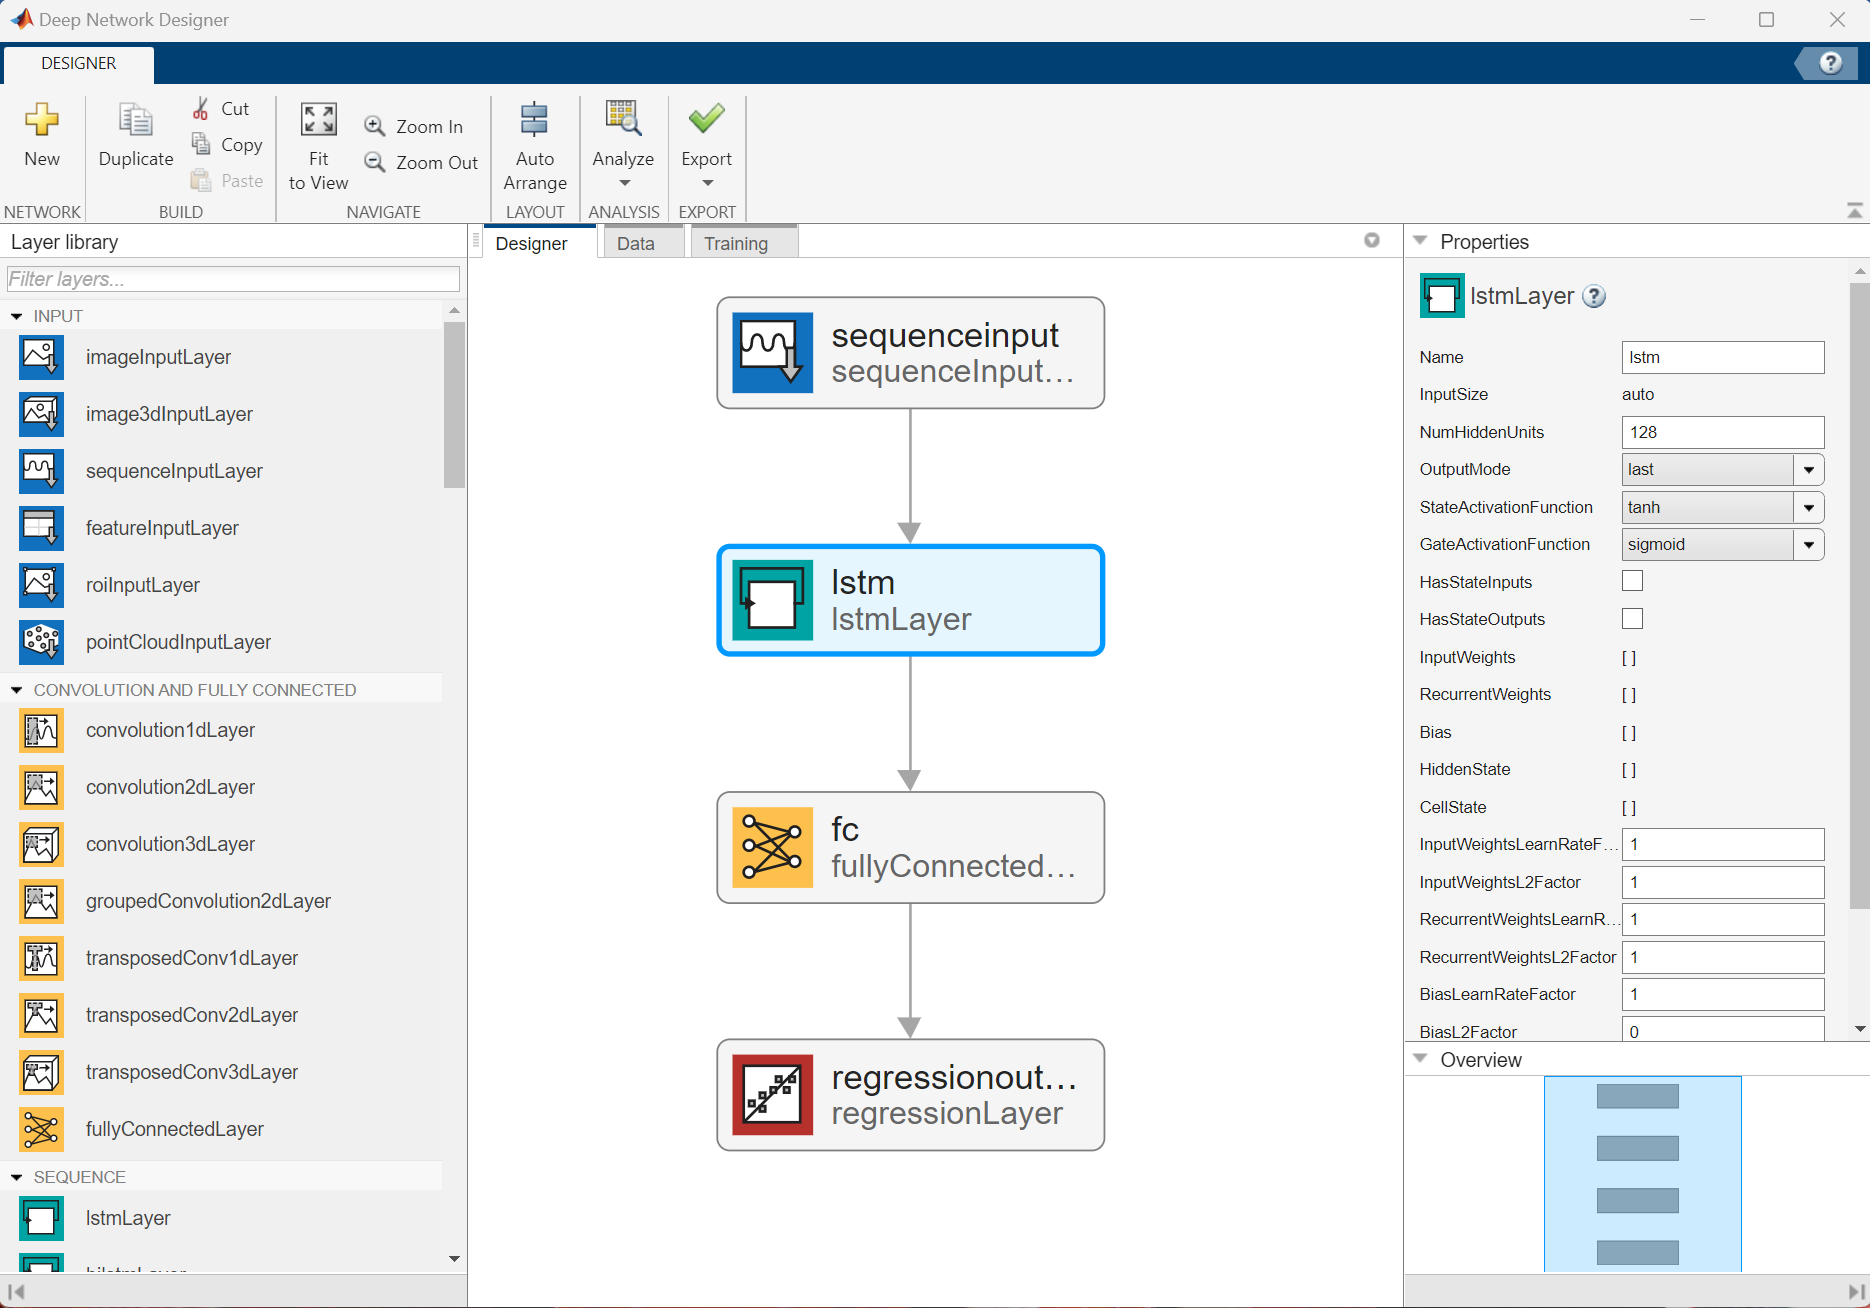

Set training options

- 参数设置

miniBatchSize = 5;%更改了miniBatchSize
rng(100);
opts = trainingOptions('sgdm',...
    'Plots','training-progress', ...
    'LearnRateSchedule', 'piecewise', ...
    'shuffle', 'never',...
    'InitialLearnRate', 0.01,...
    'MiniBatchSize', miniBatchSize,...
    'MaxEpochs', 50); 
% GPU options

To avoid waiting for the training, load the pretrained network by setting the `doTraining` flag to `false`. To train the networks using [`analyzeNetwork`](https://www.mathworks.com/help/deeplearning/ref/analyzenetwork.html) (Deep Learning Toolbox), set the `doTraining` flag to `true`. The **Training Progress** window displays progress when `Plots` in `trainingOptions` is set as `training-progress`.

Training on single CPU.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:01 |         0.81 |          0.3 |          0.0100 |
|       4 |          50 |       00:00:02 |         0.07 |      2.8e-03 |          0.0100 |
|       8 |         100 |       00:00:04 |         0.30 |      4.6e-02 |          0.0100 |
|      11 |         150 |       00:00:05 |         0.20 |      2.0e-02 |          0.0010 |
|      15 |         200 |       00:00:06 |         0.16 |      1.2e-02 |          0.0010 |
|      18 |         250 |       00:00:07 |         0.24 |      2.9e-02 |          0.0010 |
|      22 |         300 |       00:00:08 |         0.08 |      3.0

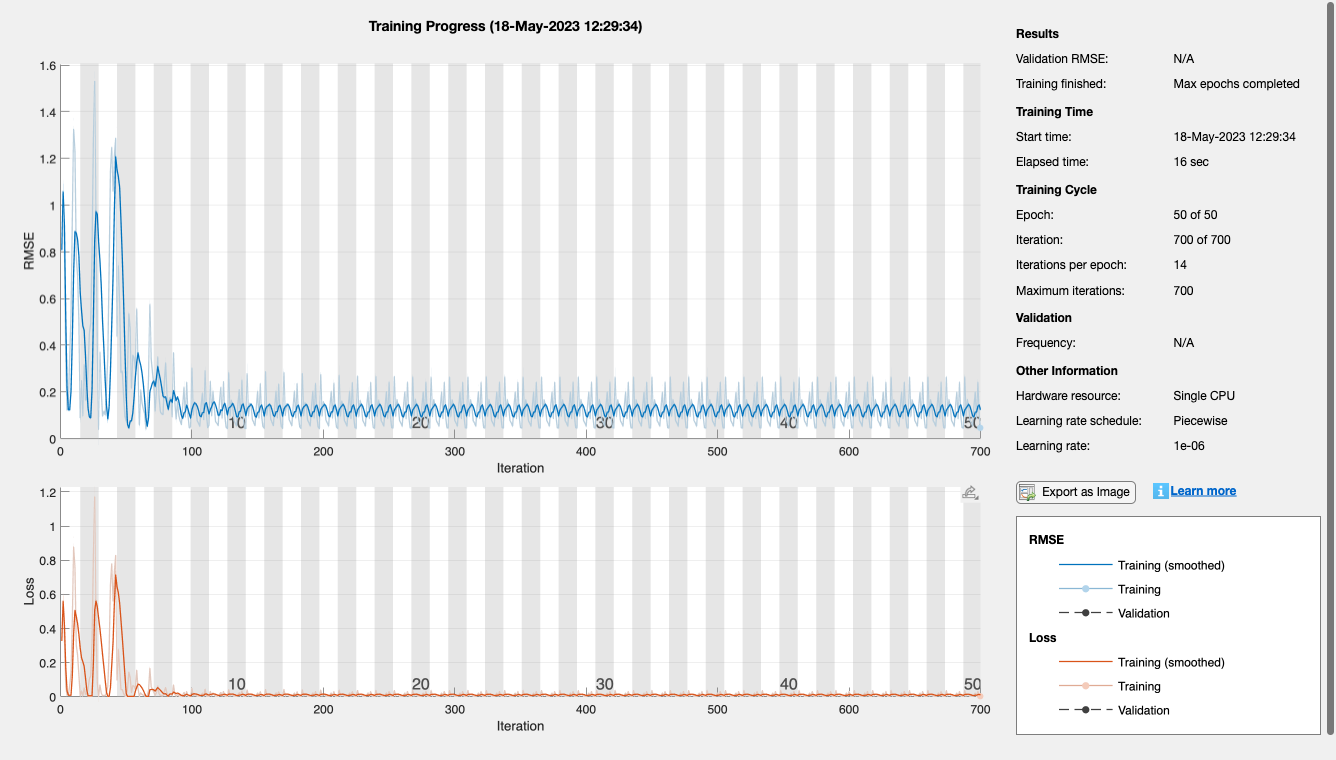

net =   SeriesNetwork with properties:

         Layers: [4×1 nnet.cnn.layer.Layer]
     InputNames: {'sequenceinput'}
    OutputNames: {'regressionoutput'}


doTraining = true;
if doTraining
    % Train the network.
    net = trainNetwork(XTrain, YTrain, layers, opts)
else
    % Load the pretrained network for the example.
    load("net.mat",'net');
end

## Forecast

YpredTest = predict(net, XTest);
YpredTrain = predict(net, XTrain);

## Visualize the data

Convert normalized data back using mean$\mu$ and standard deviation $\sigma$

predictTrain = YpredTrain(:)*sigma1 + mu1;
actualTrain = YTrain(:)*sigma1 + mu1;
predictTest = YpredTest(:)*sigma1 + mu1;
actualTest = YTest(:)*sigma1 + mu1;

Plot the performance on both training and testing data separately. Compute their root of mean squared error (RMSE).

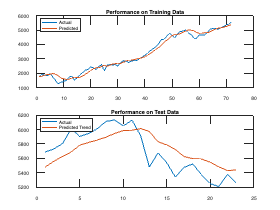

figure
subplot(2,2,[1 2])
plot(actualTrain);
hold on;
plot(predictTrain);
hold off;
title('Performance on Training Data');
legend('Actual', 'Predicted','Location','northwest');
subplot(2,2,[3 4])
plot(actualTest);
hold on;
plot(predictTest);
hold off;
title('Performance on Test Data');
legend('Actual', 'Predicted Trend','Location','northwest');

RMSE_Train = sqrt(mean((actualTrain - predictTrain).^2))

RMSE_Train = single
199.3625

new_R_train=RMSE_Train/mean(actualTrain)

new_R_train = single
0.0600

RMSE_Test = sqrt(mean((actualTest - predictTest).^2))

RMSE_Test = single
222.0845

new_R_Test=RMSE_Test/mean(actualTest)

new_R_Test = single
0.0390

## Backtest the trading strategy 

Assume initial equity to be $10,000 and index multiplier to be $1,000.

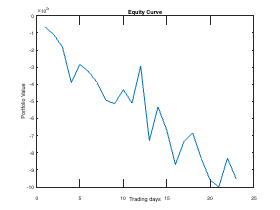

initialEquity = 10000;
M = 1000; % Index Multiplier
lastPrice = Y(end-nTest:end-1,:)*sigma1 + mu1;
signal = predictTest - lastPrice;
priceDiff = actualTest - lastPrice;
% Buy and sell signals
position = 1*(signal > 0.2) -1*(signal < -0.2);
portValue = cumsum(priceDiff.*position*M) + initialEquity;
figure
plot(portValue)
title('Equity Curve');
ylabel('Portfolio Value');
xlabel('Trading days');

fprintf('The annual profit is %d.', portValue(end)-initialEquity);

The annual profit is -9.617580e+05.

## **Supporting Functions**

Standardize data by column $\tilde{X}=\frac{X-\mu}{\sigma}$.

function [X, mu, sigma] = standardizeByCol(X)
n = size(X,1);
mu = mean(X);
sigma = std(X);
X = (X - repmat(mu,n,1)) ./ repmat(sigma,n,1);
end

Copyright 2023 The MathWorks, Inc.